clear
%data shaping
datasetFolder="./MRCLAM_Dataset1";
robotNumber = "Robot1";
% true data
groundtruth = importdata(strcat(datasetFolder,"/",robotNumber,"_Groundtruth.dat"))

groundtruth = フィールドをもつ struct :
        data: [81877×4 double]
    textdata: {4×1 cell}


groundtruth = groundtruth.data; 
% odometry data
odometry = importdata(strcat(datasetFolder,"/",robotNumber,"_Odometry.dat"));
odometry = odometry.data;

groundtruthTime = seconds(groundtruth(:,1)); %duration配列にする
groundtruthTable = array2timetable(groundtruth(:,2:4),'RowTimes',groundtruthTime,'VariableNames',{'X','Y','Theta'})

groundtruthTable = 81877×3 timetable
        Time           X          Y       Theta 
    _____________    ______    _______    ______

    1.2483e+09 秒    3.5732    -3.3328    2.3408
    1.2483e+09 秒    3.5732    -3.3328    2.3407
    1.2483e+09 秒    3.5732    -3.3329    2.3408
    1.2483e+09 秒    3.5732    -3.3329    2.3408
    1.2483e+09 秒    3.5732    -3.3329     2.341
    1.2483e+09 秒    3.5732    -3.3329    2.3411
    1.2483e+09 秒    3.5732    -3.3329    2.3411
    1.2483e+09 秒    3.5732    -3.3329    2.3411
    1.2483e+09 秒    3.5733    -3.3328    2.3407
    1.2483e+09 秒    3.5733    -3.3328    2.3406
    1.2483e+09 秒    3.5733    -3.3329    2.3406
    1.2483e+09 秒    3.5733    -3.3329    2.3407
    1.2483e+09 秒    3.5732    -3.3329     2.341
    1.2483e+09 秒    3.5732    -3.3329     2.341
    1.2483e+09 秒    3.5732    -3.3329     2.341
    1.2483e+09 秒    3.5732    -3.3329     2.341



odometryTime = seconds(odometry(:,1)); %duration配列にする
odometryTable = array2timetable(odometry(:,2:3),'RowTimes',odometryTime,'VariableNames',{'Vel','AngVel'})

odometryTable = 97890×2 timetable
        Time          Vel     AngVel
    _____________    _____    ______

    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074     0.23 
    1.2483e+09 秒    0.074     0.23 
    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074    0.229 
    1.2483e+09 秒    0.074    0.227 
    1.2483e+09 秒    0.074    0.224 
    1.2483e+09 秒    0.074    0.224 
    1.2483e+09 秒    0.074     0.22 
    1.2483e+09 秒    0.074    0.216 


syncTable = synchronize(groundtruthTable,odometryTable,'union','previous'); %tableの結合し，欠損値は直前の値を保持．
syncTable = rmmissing(syncTable); %NaNの行を削除
syncTable.Time = syncTable.Time-syncTable.Time(1) %スタート時間を0にする

syncTable = 174116×5 timetable
      Time        X          Y       Theta      Vel     AngVel
    ________    ______    _______    ______    _____    ______

    0 秒        3.5733    -3.3329     2.341    0.074    0.229 
    0.011 秒    3.5733    -3.3329     2.341    0.074    0.229 
    0.053 秒    3.5732     -3.333    2.3412    0.074    0.229 
    0.055 秒    3.5732     -3.333    2.3413    0.074    0.229 
    0.062 秒    3.5732     -3.333    2.3413    0.074    0.229 
    0.109 秒    3.5733    -3.3329    2.3411    0.074    0.229 
    0.111 秒    3.5733    -3.3329    2.3411    0.074    0.229 
    0.123 秒    3.5733    -3.3329    2.3411    0.074    0.229 
    0.148 秒    3.5733    -3.3329    2.3411    0.074    0.229 
    0.154 秒    3.5733    -3.3329    2.3411    0.074    0.229 
    0.157 秒    3.5732    -3.3329    2.3407    0.074    0.229 
    0.164 秒    3.5732    -3.3329    2.3407    0.074     0.23 
    0.195 秒    3.5732    -3.3329    2.3408    0.074     0.23 
    0.205 秒    3.5732    -3.3329    

dt = seconds(0.01);
syncTableRetime = retime(syncTable,'regular','previous','TimeStep',dt)

syncTableRetime = 149049×5 timetable
     Time        X          Y       Theta      Vel     AngVel
    _______    ______    _______    ______    _____    ______

    0 秒       3.5733    -3.3329     2.341    0.074    0.229 
    0.01 秒    3.5733    -3.3329     2.341    0.074    0.229 
    0.02 秒    3.5733    -3.3329     2.341    0.074    0.229 
    0.03 秒    3.5733    -3.3329     2.341    0.074    0.229 
    0.04 秒    3.5733    -3.3329     2.341    0.074    0.229 
    0.05 秒    3.5733    -3.3329     2.341    0.074    0.229 
    0.06 秒    3.5732     -3.333    2.3413    0.074    0.229 
    0.07 秒    3.5732     -3.333    2.3413    0.074    0.229 
    0.08 秒    3.5732     -3.333    2.3413    0.074    0.229 
    0.09 秒    3.5732     -3.333    2.3413    0.074    0.229 
    0.1 秒     3.5732     -3.333    2.3413    0.074    0.229 
    0.11 秒    3.5733    -3.3329    2.3411    0.074    0.229 
    0.12 秒    3.5733    -3.3329    2.3411    0.074    0.229 
    0.13 秒    3.5733    -3.3329    2.3411    

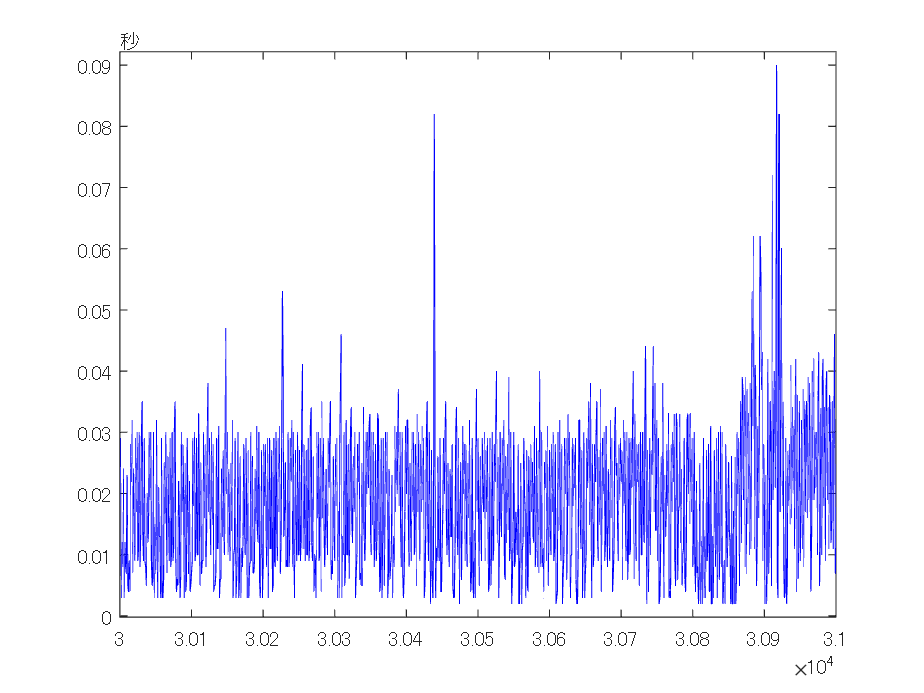

plot(groundtruthTime(2:end)-groundtruthTime(1:end-1),'b')
xlim([30000 31000])

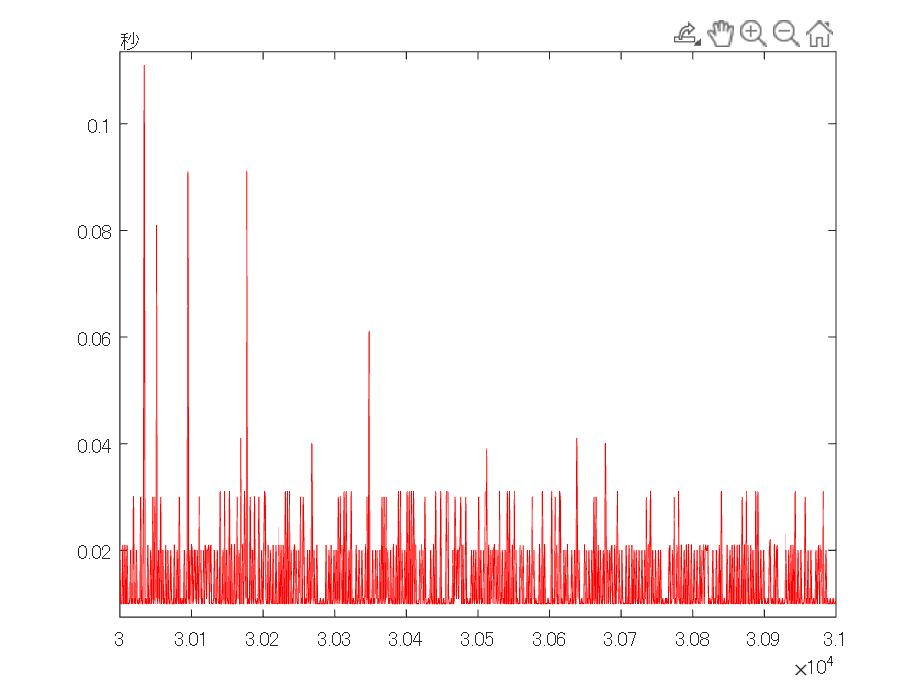

plot(odometryTime(2:end)-odometryTime(1:end-1),'r')
xlim([30000 31000])

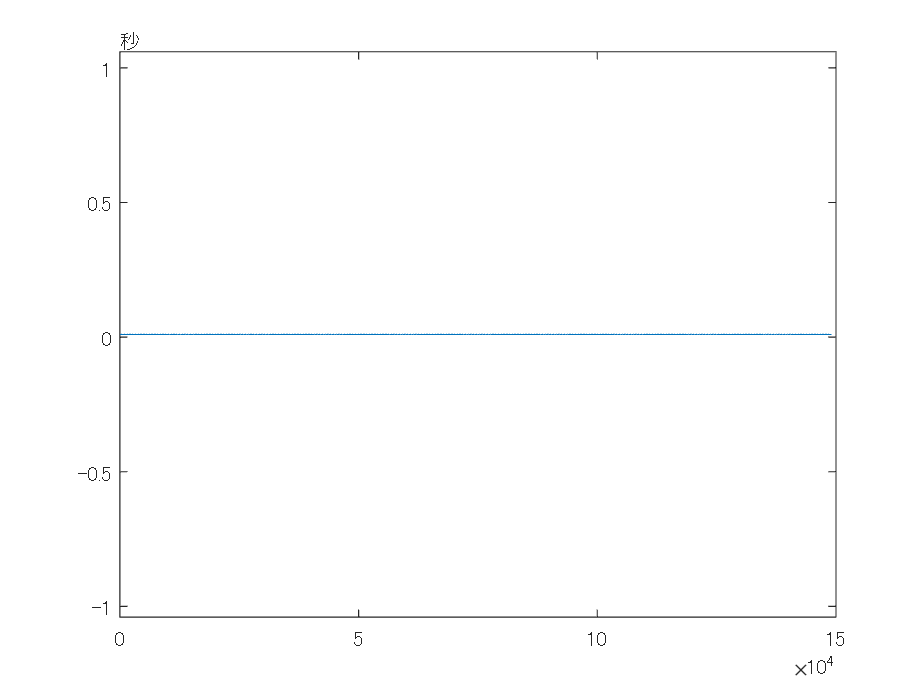


plot(syncTableRetime.Time(2:end)-syncTableRetime.Time(1:end-1))

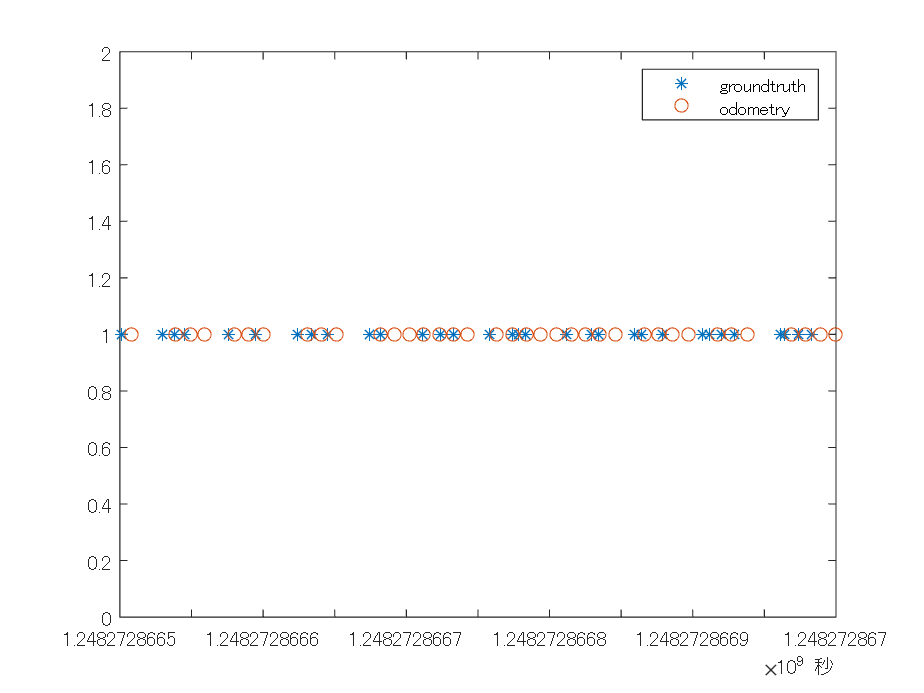

plot(groundtruthTable.Time,ones(size(groundtruthTable.Time)),'*','DisplayName','groundtruth')
hold on
plot(odometryTable.Time,ones(size(odometryTable.Time)),'o','DisplayName','odometry')
hold off
legend()
xlim([duration(346742,27,46.5) duration(346742,27,47)])